

samples_mat

samples_mat = 5×9 cell array
    { 95×3 double}    {114×3 double}    {110×3 double}    { 52×3 double}    { 56×3 double}    { 58×3 double}    {167×3 double}    {147×3 double}    {151×3 double}
    {117×3 double}    {106×3 double}    {126×3 double}    { 53×3 double}    { 64×3 double}    { 58×3 double}    {205×3 double}    {212×3 double}    {209×3 double}
    {215×3 double}    {285×3 double}    { 24×3 double}    {206×3 double}    { 97×3 double}    { 82×3 double}    { 72×3 double}    { 54×3 double}    {224×3 double}
    {242×3 double}    {249×3 double}    {307×3 double}    {144×3 double}    {156×3 double}    {152×3 double}    {475×3 double}    {438×3 double}    {399×3 double}
    {101×3 double}    {102×3 double}    {119×3 double}    {213×3 double}    {211×3 double}    {196×3 double}    { 84×3 double}    { 53×3 double}    { 74×3 double}


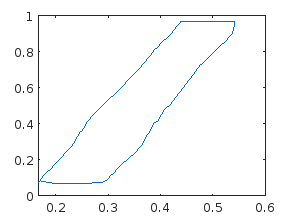

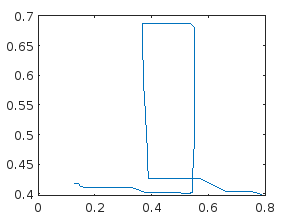

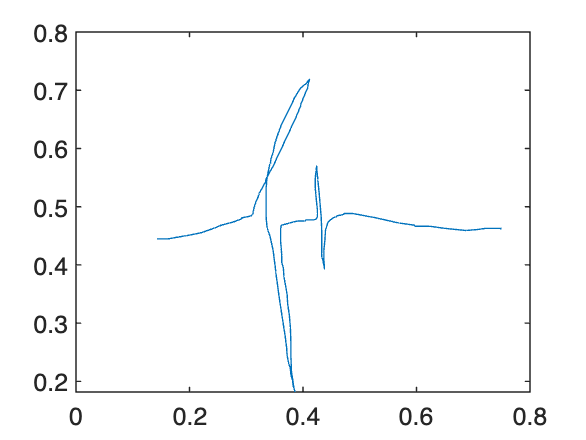

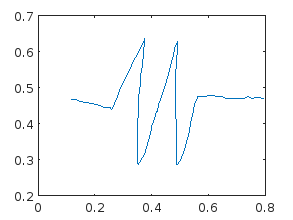

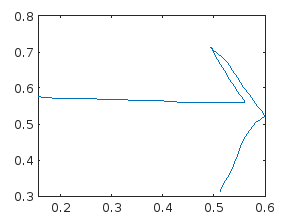



% testing ground 1


templates = samples_mat(:,1);
templates{4,1} = spring9;
for i=1:length(templates)
    figure
    plot(templates{i,1}(:,1),templates{i,1}(:,2))
end


resampled_points=resample(damper1)

resampled_points =     0.0801    0.4701
    0.1143    0.4748
    0.1490    0.4772
    0.1839    0.4773
    0.2188    0.4773
    0.2466    0.4892
    0.2524    0.5236
    0.2584    0.5580
    0.2644    0.5923
    0.2703    0.6267


resampled_templates = cellfun(@resample,templates,'UniformOutput',false)

resampled_templates = 5×1 cell array
    {64×2 double}
    {64×2 double}
    {64×2 double}
    {64×2 double}
    {64×2 double}



rotated_points = rotate_to_zero(resampled_points)

rotated_points =     0.0799    0.4597
    0.1139    0.4658
    0.1485    0.4696
    0.1833    0.4712
    0.2182    0.4726
    0.2455    0.4856
    0.2499    0.5202
    0.2545    0.5547
    0.2592    0.5893
    0.2637    0.6239


rotated_templates = cellfun(@rotate_to_zero, resampled_templates, 'UniformOutput',false)

rotated_templates = 5×1 cell array
    {64×2 double}
    {64×2 double}
    {64×2 double}
    {64×2 double}
    {64×2 double}



scaled_points = scale_to_square(rotated_points)

scaled_points =     0.1251    0.7694
    0.1783    0.7796
    0.2324    0.7859
    0.2870    0.7885
    0.3415    0.7909
    0.3843    0.8127
    0.3912    0.8706
    0.3984    0.9284
    0.4056    0.9863
    0.4127    1.0442


scaled_templates = cellfun(@scale_to_square,rotated_templates,'UniformOutput',false)

scaled_templates = 5×1 cell array
    {64×2 double}
    {64×2 double}
    {64×2 double}
    {64×2 double}
    {64×2 double}



translated_points = translate_to_origin(scaled_points)

translated_points =    -0.4022   -0.0000
   -0.3490    0.0102
   -0.2948    0.0165
   -0.2403    0.0191
   -0.1858    0.0215
   -0.1429    0.0433
   -0.1361    0.1012
   -0.1288    0.1590
   -0.1216    0.2169
   -0.1146    0.2747


translated_templates = cellfun(@translate_to_origin,scaled_templates,'UniformOutput',false)

translated_templates = 5×1 cell array
    {64×2 double}
    {64×2 double}
    {64×2 double}
    {64×2 double}
    {64×2 double}



[T_prime, score] = recognize(translated_points, translated_templates)

T_prime = 3

score = 1.3284

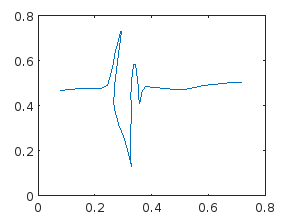


plot(resampled_points(:,1), resampled_points(:,2))

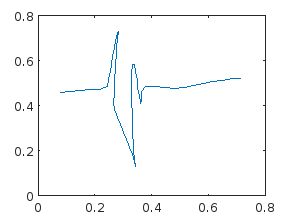


plot(rotated_points(:,1), rotated_points(:,2))

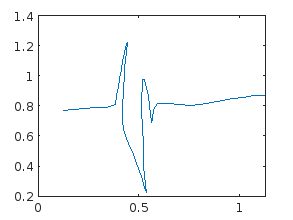


plot(scaled_points(:,1), scaled_points(:,2))

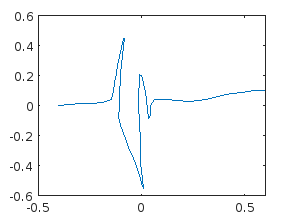


plot(translated_points(:,1), translated_points(:,2))